# How to use the new Shear Force Banding Moment Toolbox

#### Create the SFBMProb object using:

#### SFBMProb(name, length, supports)

#### name = string; length = double, support = (1,2) double

prob = SFBMProb("Problem 1", 20, [2, 18]);

#### Add loads to/Delete loads from the SFBMProb object using: (Add/Remove)MomentLoad, (Add/Remove)PointLoad, or (Add/Remove)DistLoad

Note: Each load has two inputs, the value of the load, and its location. 

For instance to add a point load, we use

prob.AddPointLoad(50, 10);

We can Solve the problem:

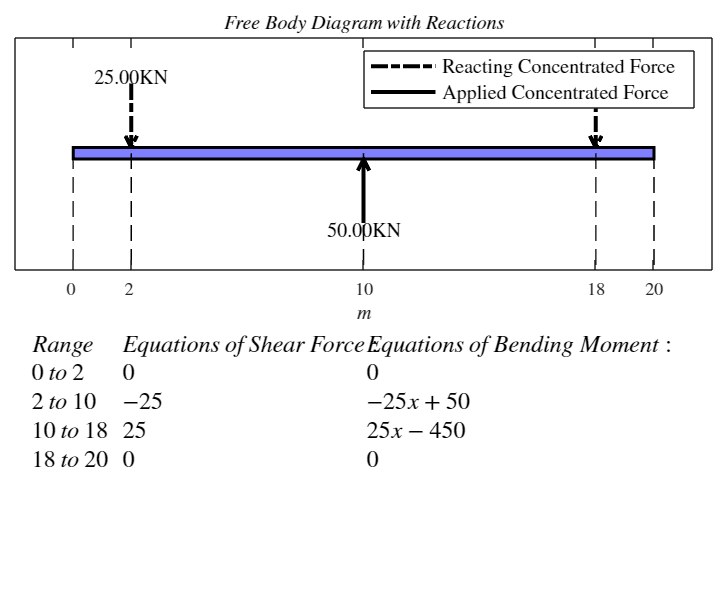

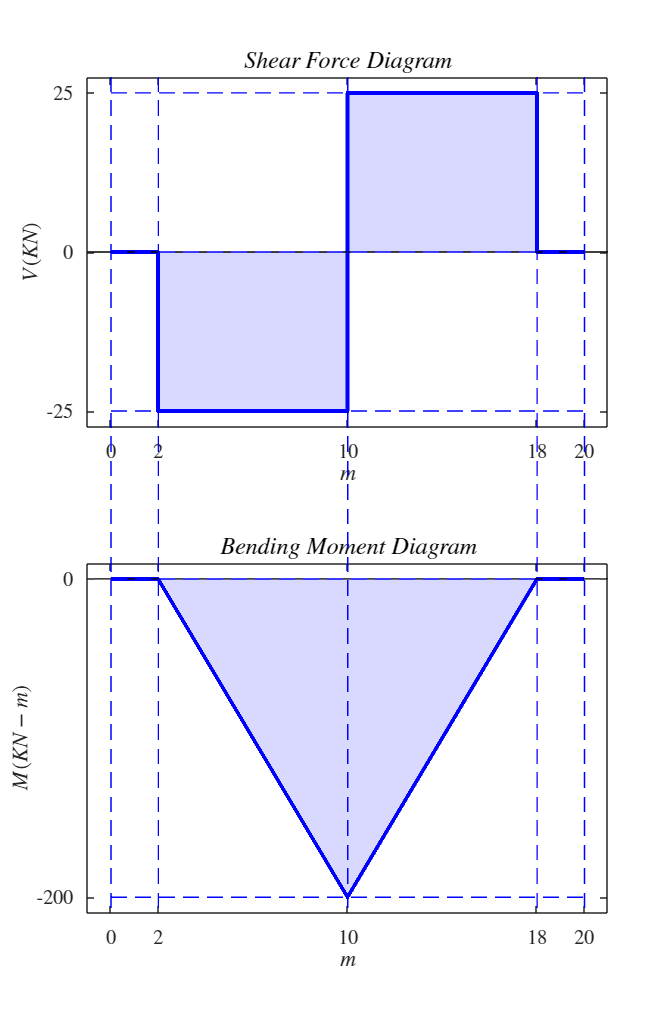

prob.Solve();

[maxshearforce, loc_maxsf] = prob.GetMaxShearForce()

maxshearforce = 25

loc_maxsf = 10

[maxbendmoment, loc_maxbm] = prob.GetMaxBendMoment()

maxbendmoment = 0

loc_maxbm = 0